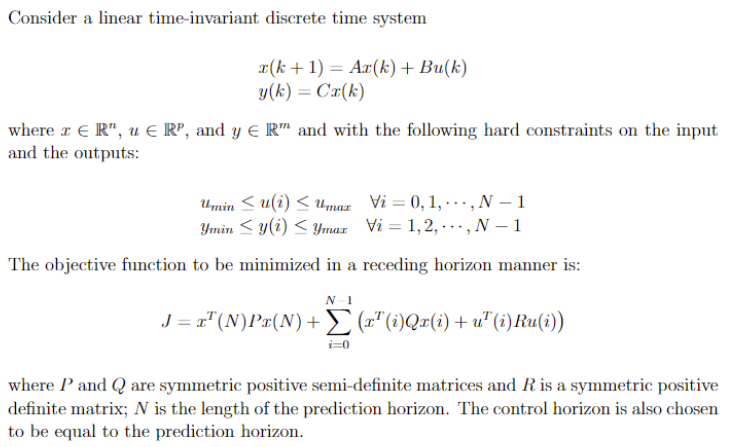

Below is a sample code to simulate a linear MPC.

**get_QP** function which forms the QP matrices 

**do_MPC** function calculates the receeding horizon controller for the given system.

## System setup

% clc; clear;

% define a discrete time linear system
% x(k+1) =A_d*x(k) + B_d*u(k)
% y(k) = C_d*x(k)

% A_d = [1 0 0; 1 2 0; 1 2 3];
% B_d = [1 1; 1 1; 1 1];
% C_d = eye(3,3);


system.A = operator.A;
system.B = operator.B;
system.C = operator.C;
system.n = size(system.A,2);
system.p = size(system.B,2);
system.m = size(system.C,2);



## MPC setup

mpc.dT = 0.1; % Discretization and simulation timestep
mpc.N = 30; % prediction horizon

% define MPC cost
% stage cost (running cost): x'*Q*X + u'*R*u
% terminal cost: x'*P'x
mpc.Q = eye(system.n ,system.n);
mpc.R = eye(system.p ,system.p);
mpc.P = eye(system.n ,system.n);

% input bounds
bounds.u_min = [-10];%[-3; -5];
bounds.u_max = [10];%[5; 5];

% output bounds
bounds.y_min = [-10;-10];
bounds.y_max = [10;10];

## **Get QP Matrices**

% collect info needed for QP
[F, G, A_ineq, B_ineq] = get_QP(system,mpc,bounds);

## **Simulate MPC with quadprog**

% initialize
x0 = [0.5;0.5];
z0 = get_basis(x0,basis);
t = 0;

% unpack info
p = system.p;
dT = mpc.dT;

% data logging
Z_log = z0; T_log = t;
U_log = [];

% simulation loop
max_iter = 150;
z = z0;
for i = 1:max_iter

    % get MPC controller
    U = do_MPC(G,z'*F',A_ineq,B_ineq,z);
    u = U(1:p);

    % simulate discrete time system
    z = operator.A*z + operator.B*u;

    % log data
    T_log = [T_log, t];
    Z_log = [Z_log, z];
    U_log = [U_log, u];

    % update sim time
    t = i*dT;
end

## Plots

tiledlayout(3,1)
X_log = operator.C*Z_log;
nexttile
plot(T_log,X_log, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))

ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');

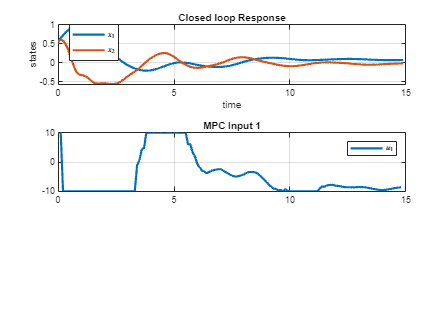

set(LEG,'interpreter','latex')

nexttile
plot(T_log(1:end-1),U_log(1,:),'LineWidth',2); grid on;
title(sprintf('MPC Input 1'))
LEG = legend('$u_1$');
set(LEG,'interpreter','latex')

nexttile(1)
legend("Position", [0.15599,0.8213,0.10893,0.10476])

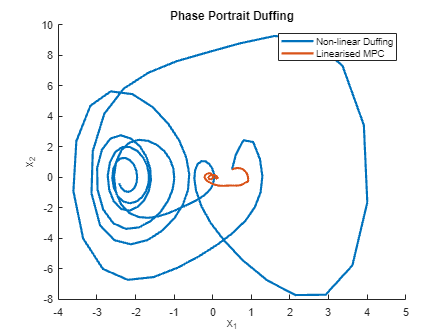

% Solve the differential equation
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,2));
[~, data_control] = ode45(@(t,x) dynamics_duffing_MPC(t, x, U_log, T_log), T_log, x0, options);

figure
hold on
p1 = plot(data_control(:,1),data_control(:,2),'DisplayName','Non-linear Duffing');
p2 = plot(X_log(1,:),X_log(2,:),'DisplayName','Linearised MPC');
title(sprintf('Phase Portrait Duffing'))
legend([p1,p2])
ylabel('x_2')
xlabel ('x_1');

## Helper functions

getting a QP representation given the discrete time linear system and MPC paramters

%function [F, G, A_ineq, B_ineq] = get_QP(system,mpc,bounds)
% Inputs
% system.A (system dynamics)                    : n x n
% system.B (control input)                      : n x p
% system.C (system output)                      : n x m
% mpc.P (termail cost)                          : n x 1
% mpc.Q (state cost)                            : n(N-1) x n(N-1)
% mpc.R (control cost)                          : p(N-1) x p(N-1)
% mpc.N is prediction horizon                   : scalar
% bounds.u_min is min the control bound         : scalar
% bounds.u_max is max the control bound         : scalar
% bounds.y_min is min the output bound          : scalar
% bounds.y_max is min the output bound          : scalar

% Outputs
% G (augmented cost)                        : p(N) x p(N)
% F (augmented cost)                        : p(N) x 1
% augmented cost                            : 1/2 * X^T * G * X + X^T * F * x0
% A_ineq (augmented ineq constraint A)      : (p+m)(N) x (p+m)(N)
% B_ineq (augmented ineq constraint b)      : 2(p+m)(N) x 1
% augmented ineq constraint                 : A_ineq * X <= b_ineq + b_ineqx0 * x0



solving the MPC as  QP problem

%function U = do_MPC(G,F,A_ineq,B_ineq,x)
% Inputs
% G (augmented cost)                        : p(N) x p(N)
% F (augmented cost)                        : p(N) x 1
% A_ineq (augmented ineq constraint A)      : (p+m)(N) x (p+m)(N)
% B_ineq (augmented ineq constraint b)      : 2(p+m)(N) x 1
% x (operating point)                       : n x 1

% Outputs
% U (MPC output)                            : p x 1